clc;
clear;
close all;

%% ----------------------------------
% Parameters
%% ----------------------------------
N = 1000;              % Number of bits
Tb = 1;                % Bit duration
Fs = 100;              % Sampling frequency
t = 0:1/Fs:Tb-1/Fs;

SNR_dB = 10;           % SNR in dB

%% ----------------------------------
% 1. Binary PAM (2-PAM)
%% ----------------------------------
bits = randi([0 1], 1, N);

% Mapping: 0 -> -1, 1 -> +1
symbols_2pam = 2*bits - 1;

% Signal generation
tx_signal = kron(symbols_2pam, ones(1,length(t)));

% AWGN Channel
rx_signal = awgn(tx_signal, SNR_dB, 'measured');

%% ----------------------------------
% Matched Filter Receiver
%% ----------------------------------
h = ones(1,length(t));   % matched filter

rx_filtered = conv(rx_signal, h, 'same');

% Sampling
sample_points = length(t)/2 : length(t) : length(rx_filtered);
samples = rx_filtered(round(sample_points));

% Decision (threshold = 0)
detected_bits = samples > 0;

% BER
BER_2PAM = sum(bits ~= detected_bits) / N;
disp(['BER (2-PAM): ', num2str(BER_2PAM)]);

BER (2-PAM): 0


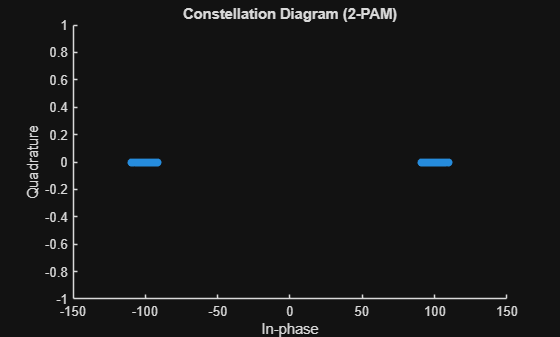


%% ----------------------------------
% Constellation Diagram (2-PAM)
%% ----------------------------------
figure;
scatter(samples, zeros(size(samples)), 'filled');
title('Constellation Diagram (2-PAM)');
xlabel('In-phase');
ylabel('Quadrature');

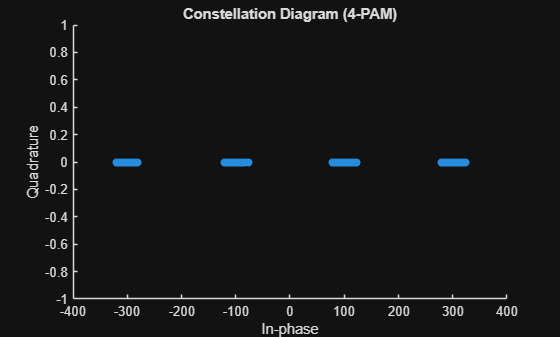


%% ----------------------------------
% 2. Four-Level PAM (4-PAM)
%% ----------------------------------
M = 4;
k = log2(M);

data = randi([0 1], 1, N*k);

% Group bits into symbols
data_reshape = reshape(data, k, []).';

% Mapping (Gray coding)
mapping = [-3 -1 1 3];
symbols_index = bi2de(data_reshape, 'left-msb') + 1;
symbols_4pam = mapping(symbols_index);

% Signal generation
tx_4pam = kron(symbols_4pam, ones(1,length(t)));

% AWGN Channel
rx_4pam = awgn(tx_4pam, SNR_dB, 'measured');

%% ----------------------------------
% Receiver (Matched Filter)
%% ----------------------------------
rx_filtered_4pam = conv(rx_4pam, h, 'same');

sample_points = length(t)/2 : length(t) : length(rx_filtered_4pam);
samples_4pam = rx_filtered_4pam(round(sample_points));

% Decision thresholds
detected_symbols = zeros(size(samples_4pam));

for i = 1:length(samples_4pam)
    if samples_4pam(i) < -2
        detected_symbols(i) = -3;
    elseif samples_4pam(i) < 0
        detected_symbols(i) = -1;
    elseif samples_4pam(i) < 2
        detected_symbols(i) = 1;
    else
        detected_symbols(i) = 3;
    end
end

%% ----------------------------------
% Constellation Diagram (4-PAM)
%% ----------------------------------
figure;
scatter(samples_4pam, zeros(size(samples_4pam)), 'filled');
title('Constellation Diagram (4-PAM)');
xlabel('In-phase');
ylabel('Quadrature');


%% ----------------------------------
% Theoretical BER (2-PAM in AWGN)
%% ----------------------------------
EbN0 = 10^(SNR_dB/10);

BER_theoretical = 0.5 * erfc(sqrt(EbN0));
disp(['Theoretical BER (2-PAM): ', num2str(BER_theoretical)]);

Theoretical BER (2-PAM): 3.8721e-06
